# Direct kinematic

planar arm

import ETS2.*
a1 = 1;
a2 = 1;
E = Rz('q1') * Tx(a1)*Rz('q2') * Tx(a2)

 
E = 
Rz(q1)Tx(1)Rz(q2)Tx(1)


E.teach

creating new ETS plot


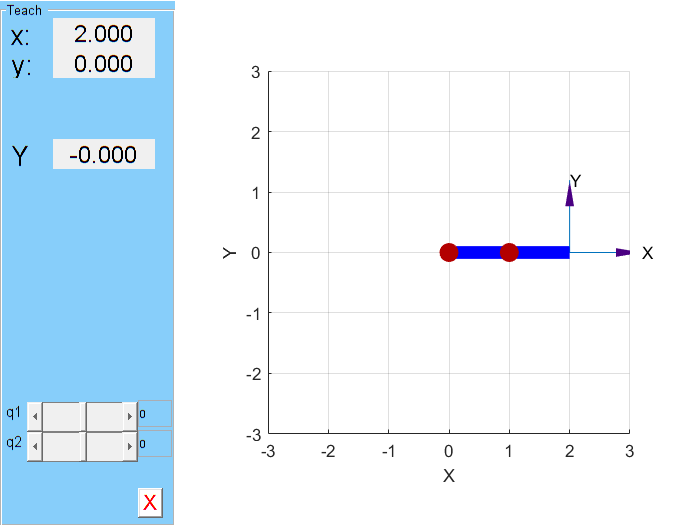

F = gcf;F.Visible = true;

## Denavith-Hartenberg convention

`Link` object, are connected with the command `SerialLink which create a SerialLink object`

subclasses:

- Revolute

- Prismatic

in this way the robot is embedded in **SE(3)**

% create the same robot of before

robot = SerialLink([Revolute('a',1) Revolute('a',1) ], 'name','ROB')

 
robot = 
 
ROB:: 2 axis, RR, stdDH, slowRNE                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


% forward kinematic
robot.fkine([30 30],'deg')
robot.fkine(theta(1:2))

 

ans = 
    0.6642   -0.7476         0    -0.248
    0.7476    0.6642         0    0.3378
         0         0         1         0
         0         0         0         1


## PUMA 560

mdl_puma560 % script that import the puma 560

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & \cos\left(\theta_{1}+\theta_{2}\right)+\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & \sin\left(\theta_{1}+\theta_{2}\right)+\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p560

subplot(1,3,1)
p560.plot(qz)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


title('zero angle')
subplot(1,3,2)
p560.plot(qr), title('ready')
subplot(1,3,3)
p560.plot(qn), title('nominal: dextrous working pose')


clf
p560.tool = SE3(0,0,0)
p560.plot(qn), set(gcf,'Visible','on')

% change tool and base frame
p560.tool = SE3.Ry(pi);
p560.plot3d(qn)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


clf

## inverse kinematic

### planar 2 links arm

 
rob = 
 
ROB:: 2 axis, RR, stdDH, slowRNE                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


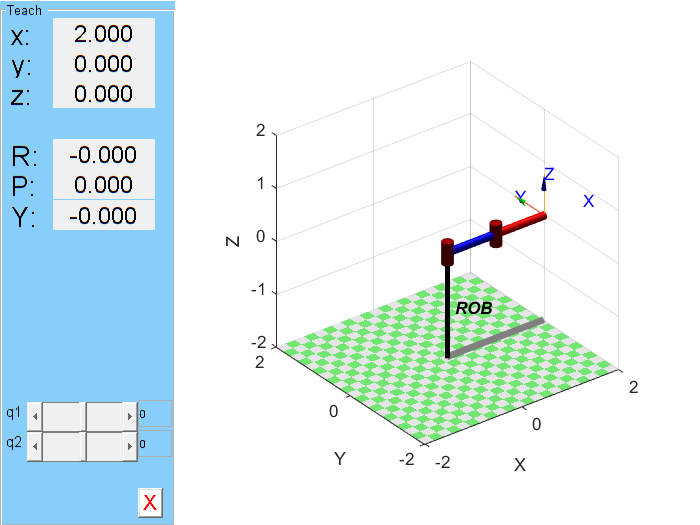

rob = SerialLink([Revolute('a',1) Revolute('a',1) ], 'name','ROB')
clf
rob.teach, set(gcf,'visible','on')
